# Моделирование АЦП

В данной модели используется АЦП, который перед оцифровкой приподнимает сигнал (добавляет постоянную составляющую) с целью избежания отрицательных значений сигнала.

Описание сигнала:

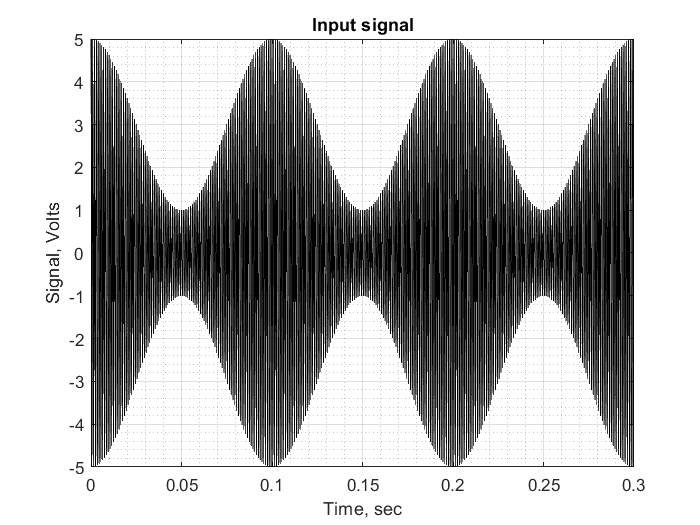

clear; close all;

F  = 10;                % частота информационного сигнала
f0 = 1e3;               % несущая частота
fs = 1e3*f0;            % частота дискретизации (для расчетов)
dt = 1/fs;              % период дискретизации
t  = 0:dt:3/F-dt;       % вектор времени
A0 = 3;                 % постоянная составляющая АМ-сигнала
A  = 2;                 % амплитуда информационного сигнала
input  = A0+A*cos(2*pi*F*t);
input  = input.*cos(2*pi*f0*t);
plot(t,input,'-k'); grid on; grid minor;
xlabel('Time, sec'); ylabel('Signal, Volts');
title('Input signal');

Характеристики АЦП:

N      = 08;            % разрядность АЦП
r      = 2^N;           % кол-во уровней квантования
V_max  = 50;            % максимальное значение сигнала для корректной оцифровки
V_mean = V_max/2;       % постоянная составляющая АЦП (для удаления отрицательной части сигнала)
delta  = V_max/r;       % шаг квантования
new_fs = 10*f0;         % частота дискретизации АЦП
Quant  = delta*(0:r-1); % сетка квантования
fprintf('Sample frequency  = %g Hz\n',new_fs);

Sample frequency  = 10000 Hz


fprintf('Quantization step = %g V\n',delta);

Quantization step = 0.195312 V


Прохождение сигнала перед АЦП

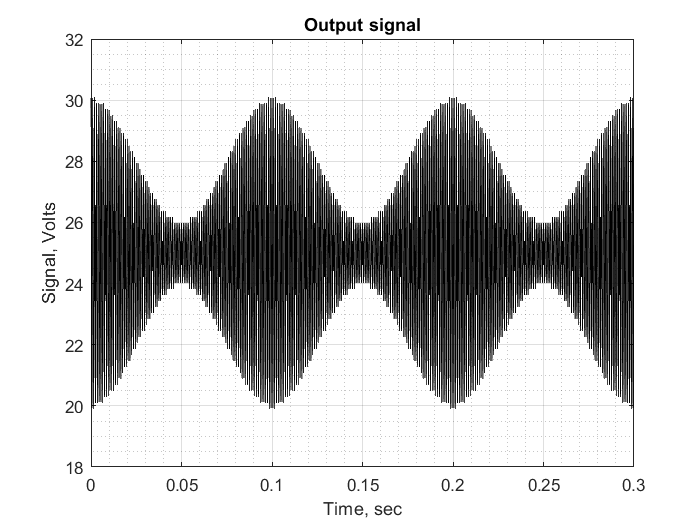

resampled_signal  = downsample(input+V_mean,round(fs/new_fs));
dt = 1/new_fs;
t  = 0:dt:3/F-dt;
n  = length(t);         % кол-во отсчетов вектора времени
output = zeros(1,n);
for i = 1:n
    [~,k] = min(abs(resampled_signal(i)-Quant));
    output(i) = Quant(k);
end
plot(t,output,'-k'); grid on; grid minor;
xlabel('Time, sec'); ylabel('Signal, Volts');
title('Output signal');

Сигнал ошибки, вызванный эффектом квантования:

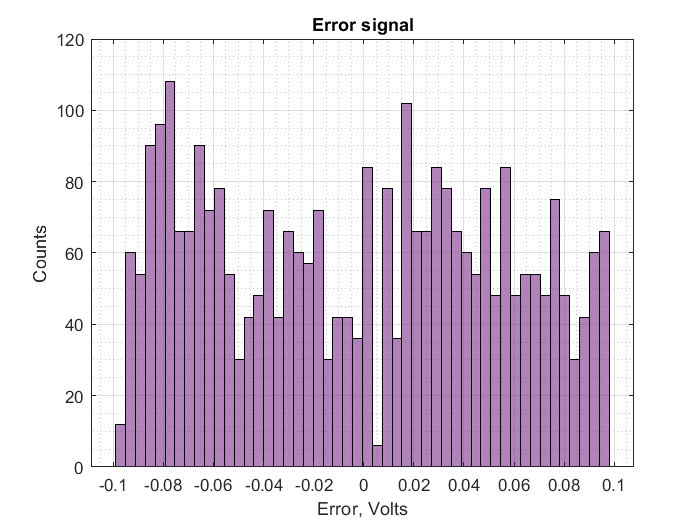

epsilon = output-resampled_signal;
histogram(epsilon,50,'FaceColor','#7E2F8E'); grid on; grid minor;
xlabel('Error, Volts'); ylabel('Counts');
title('Error signal');

Информационные характеристики сигнала на выходе АЦП:

output_code.Samples = (0:n-1)';                      % отсчеты времени (такт)
output_code.Signal  = round(output/delta)';          % перевод реальных значений
                                                     % сигнала в относительные единицы
output_code.Signal  = dec2bin(output_code.Signal,N); % формирование двоичного кода сигнала
bits  = N*n;                                         % объем передаваемой информации (бит)
speed = bits/t(end)/1024;                            % минимальная скорость передачи данных для
                                                     % поточной обработки
speed = ceil(speed/8);
if speed>1000
    speed = ceil(speed/1024);
    str   = 'MBytes';
else
    str   = 'KBytes';
end
fprintf(['For comfortable streaming processing, the system must have a speed at least\n%g' ...
    ' %s/s\n'],speed,str);

For comfortable streaming processing, the system must have a speed at least
10 KBytes/s


disp('************************************************************************************');

************************************************************************************


fprintf('Sample:\t\tCode:\n');

Sample:		Code:


for i = 1:100
    fprintf('%g\t\t%s\n',output_code.Samples(i),output_code.Signal(i,:))
end

0		10011010
1		10010101
2		10001000
3		01111000
4		01101011
5		01100110
6		01101011
7		01111000
8		10001000
9		10010101
10		10011010
11		10010101
12		10001000
13		01111000
14		01101011
15		01100110
16		01101011
17		01111000
18		10001000
19		10010101
20		10011010
21		10010101
22		10001000
23		01111000
24		01101011
25		01100111
26		01101011
27		01111000
28		10001000
29		10010101
30		10011001
31		10010101
32		10001000
33		01111000
34		01101011
35		01100111
36		01101100
37		01111000
38		10001000
39		10010100
40		10011001
41		10010100
42		10001000
43		01111000
44		01101100
45		01100111
46		01101100
47		01111000
48		10001000
49		10010100
50		10011001
51		10010100
52		10001000
53		01111000
54		01101100
55		01100111
56		01101100
57		01111000
58		10001000
59		10010100
60		10011001
61		10010100
62		10001000
63		01111000
64		01101100
65		01100111
66		01101100
67		01111000
68		10001000
69		10010100
70		10011001
71		10010100
72		10001000
73		01111000
74		01101100
75		01101000
76		01101100
77		01111